---

title: "PEP_wp4_beh"

output: html_document

date: "2023-12-15".([category,'_RDM']).rdm_cor_rdm

--- house keeping ---

% clear workspace
clear;
clc;

% add folder with helper function tp to path
function_folder = fullfile(pwd, 'functions');
addpath(function_folder)

% if missing create a figure folder
if ~exist(fullfile(pwd,'figures'), 'dir')
    mkdir(fullfile(pwd,'figures'));
end


--- loading files ---

% details of subjects
cfg.subNums = [201:216,218:222,224:238,240:244]; % 217, 223, and 239 excluded because of bad drawings
cfg.n = length(cfg.subNums);
cfg.exp_num = 2;

% add scene categories and tasks
cfg.categories = {'bedroom', 'livingroom'};
cfg.tasks = {'categorization'};

% initialize data structure
d = struct;
%load('d2.mat');
%load('cfg2.mat');

% load files
d = load_files(cfg, d);

Loaded: 201
Loaded: 202
Loaded: 203
Loaded: 204
Loaded: 205
Loaded: 206
Loaded: 207
Loaded: 208
Loaded: 209
Loaded: 210
Loaded: 211
Loaded: 212
Loaded: 213
Loaded: 214
Loaded: 215
Loaded: 216
Loaded: 218
Loaded: 219
Loaded: 220
Loaded: 221
Loaded: 222
Loaded: 224
Loaded: 225
Loaded: 226
Loaded: 227
Loaded: 228
Loaded: 229
Loaded: 230
Loaded: 231
Loaded: 232
Loaded: 233
Loaded: 234
Loaded: 235
Loaded: 236
Loaded: 237
Loaded: 238
Loaded: 240
Loaded: 241
Loaded: 242
Loaded: 243
Loaded: 244



% load colormap
load('figures/colormaps.mat');
cfg.colormaps = colormaps;

% other standard configurations
cfg.FontName = 'Helvetica';
cfg.FontSize = 20;


--- timing ----

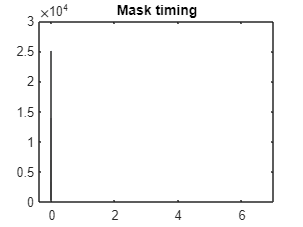

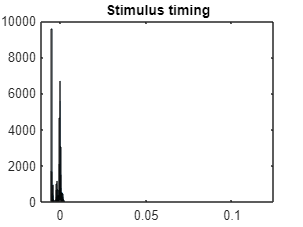

Timin is calculated


% to calculate and plot the timing
[timing, d]  = calculate_timing(d, cfg);

--- transfrom data (and trial and subject exclusion) ---

% make trial exclusion
d = trial_exclusion(d);

0 trials were < 0.1 s
266 trials were > 3 s
6 trials displayed stimulus on wrong frame
11 trials displayed mask on wrong frame
276 trials have been excluded
This equals 0.0055466 % of all trials



% transform data (adds a couple new subtables)
d = transform_data(d, cfg);

Data transformation has been performed




% make subject exclusion -
[d, cfg] = subject_exclusion(d, cfg);

Subject 201 meets all inclusion criteria
Subject 202 meets all inclusion criteria
Subject 203 meets all inclusion criteria
Subject 204 meets all inclusion criteria
Subject 205 meets all inclusion criteria
Subject 206 meets all inclusion criteria
Subject 207 meets all inclusion criteria
Subject 208 meets all inclusion criteria
Subject 209 meets all inclusion criteria
Subject 210 meets all inclusion criteria
Subject 211 meets all inclusion criteria
Subject 212 meets all inclusion criteria
Subject 213 meets all inclusion criteria
Subject 214 meets all inclusion criteria


Subject 216 meets all inclusion criteria
Subject 218 meets all inclusion criteria
Subject 219 meets all inclusion criteria
Subject 220 meets all inclusion criteria
Subject 221 meets all inclusion criteria
Subject 222 meets all inclusion criteria
Subject 224 meets all inclusion criteria
Subject 225 meets all inclusion criteria
Subject 226 meets all inclusion criteria
Subject 227 meets all inclusion criteria
Subject 228 meets all inclusion criteria
Subject 229 meets all inclusion criteria
Subject 230 meets all inclusion criteria
Subject 231 meets all inclusion criteria
Subject 232 meets all inclusion criteria
Subject 233 meets all inclusion criteria
Subject 234 meets all inclusion criteria
Subject 235 meets all inclusion criteria
Subject 236 meets all inclusion criteria
Subject 237 meets all inclusion criteria
Subject 238 meets all inclusion criteria
Subject 240 meets all inclusion criteria
Subject 241 meets all inclusion criteria
Subject 242 meets all inclusion criteria
Subject 243 meet


%% CHECK If RATING ARE CORRECT

--- performance --- 

% calculate performance
perf = make_perf(d, cfg);

Performance is calculated
Mean accuracy: 0.71861
Mean RT: 0.82516



--- HISTOGRAMS ---

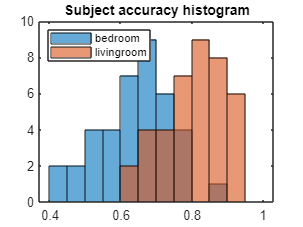

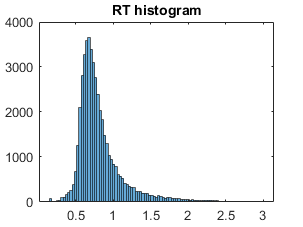

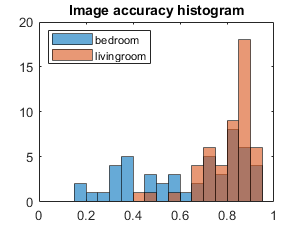

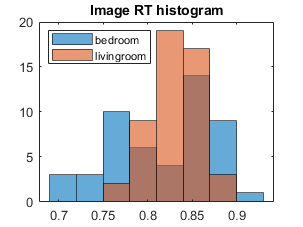

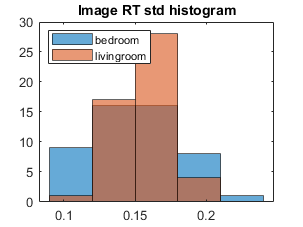

% plot histograms
hist_plots_figures = hist_plots(d, cfg);

--- intersubject correaltions ---

Plotting and saving inter-subject RDM for task:mean_neg_RT and bedroom
Plotting and saving inter-subject RDM for task:mean_trial_accuracy and bedroom
Plotting and saving inter-subject RDM for task:IES and bedroom
Plotting and saving inter-subject RDM for task:mean_neg_RT and livingroom
Plotting and saving inter-subject RDM for task:mean_trial_accuracy and livingroom
Plotting and saving inter-subject RDM for task:IES and livingroom


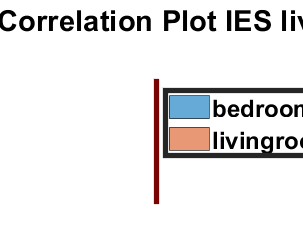

Compare categories


% calculate and plot the correlations of rating between subjects

% get variables of interest
cfg.variables_of_interest = {'mean_neg_RT', 'mean_trial_accuracy', 'IES'};
cfg.colormap = cfg.colormaps.white_zero2;
cfg.plot_rdm = false;
cfg.dissimilarity = true;

[cor_plots, d] = intersub_cor(d, cfg);

--- split-half reliability of inter-subject correaltions ---

Plotting and saving inter-subject RDM for task:mean_neg_RT and bedroom
Plotting and saving inter-subject RDM for task:mean_trial_accuracy and bedroom
Plotting and saving inter-subject RDM for task:IES and bedroom
Plotting and saving inter-subject RDM for task:mean_neg_RT and livingroom
Plotting and saving inter-subject RDM for task:mean_trial_accuracy and livingroom
Plotting and saving inter-subject RDM for task:IES and livingroom
Compare categories
Plotting and saving inter-subject RDM for task:mean_neg_RT and bedroom
Plotting and saving inter-subject RDM for task:mean_trial_accuracy and bedroom
Plotting and saving inter-subject RDM for task:IES and bedroom
Plotting and saving inter-subject RDM for task:mean_neg_RT and livingroom
Plotting and saving inter-subject RDM for task:mean_trial_accuracy and livingroom
Plotting and saving inter-subject RDM for task:IES and livingroom


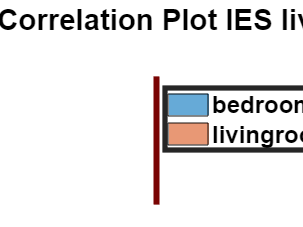

Compare categories


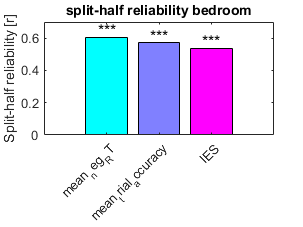

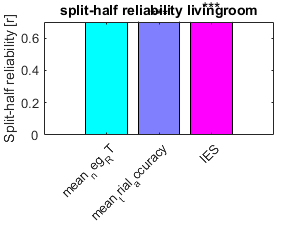

% calculate and plot the split-half reliability of inter-subject correaltions

% get variables of interest
cfg.variables_of_interest = {'mean_neg_RT', 'mean_trial_accuracy', 'IES'};

d = split_half_reliabiliy(d, cfg);

--- correlate generated images of typical drawings with DNN layer --- 

% preparation
cfg.dnn = 'vgg16_imagenet';
cfg.layer_type = 'late';
[cfg.parent_dir, ~, ~] = fileparts(pwd);
images = struct;
cfg.file_format = 'png';
cfg.plot_rdm = 1;
cfg.RDM_of_DNNS = 1;
cfg.analysis_name = 'Own_drawing_DNN_RDM';
d.DNN.(cfg.dnn).(cfg.analysis_name) = struct;
drw_group = 'own';
cfg.colormap = cfg.colormaps.typDrwColormap;
cfg.folder_path = fullfile(cfg.parent_dir, 'image_similarities','drawings_draw3D', 'draw3D_images_exp2', drw_group);

% load images
images.(cfg.analysis_name) = load_images(cfg);

Loaded image: 201_bed_gen1.png
Loaded image: 201_bed_gen2.png
Loaded image: 201_bed_gen3.png
Loaded image: 202_bed_gen1.png
Loaded image: 202_bed_gen2.png
Loaded image: 202_bed_gen3.png
Loaded image: 203_bed_gen1.png
Loaded image: 203_bed_gen2.png
Loaded image: 203_bed_gen3.png
Loaded image: 204_bed_gen1.png
Loaded image: 204_bed_gen2.png
Loaded image: 204_bed_gen3.png
Loaded image: 205_bed_gen1.png
Loaded image: 205_bed_gen2.png
Loaded image: 205_bed_gen3.png
Loaded image: 206_bed_gen1.png
Loaded image: 206_bed_gen2.png
Loaded image: 206_bed_gen3.png
Loaded image: 207_bed_gen1.png
Loaded image: 207_bed_gen2.png
Loaded image: 207_bed_gen3.png
Loaded image: 208_bed_gen1.png
Loaded image: 208_bed_gen2.png
Loaded image: 208_bed_gen3.png
Loaded image: 209_bed_gen1.png
Loaded image: 209_bed_gen2.png
Loaded image: 209_bed_gen3.png
Loaded image: 210_bed_gen1.png
Loaded image: 210_bed_gen2.png
Loaded image: 210_bed_gen3.png
Loaded image: 211_bed_gen1.png
Loaded image: 211_bed_gen2.png
Loaded i

analysis Own_drawing_DNN_RDM - layer #1 - category: bedroom
Length of labels do not match matrix dimensions


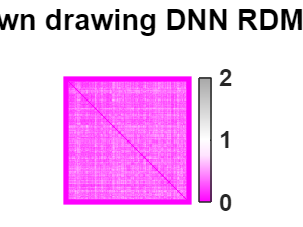

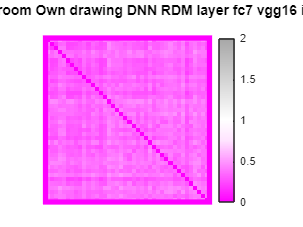

analysis Own_drawing_DNN_RDM - layer #1 - category: livingroom
Length of labels do not match matrix dimensions


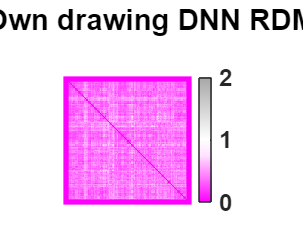

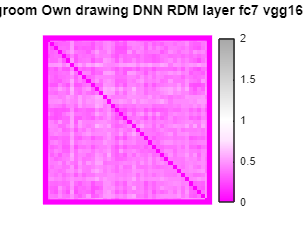


% get correaltion of images from DNN
[d, cfg] = get_dnn_layer_similarity(d, images.(cfg.analysis_name), cfg);

Calculated correaltion of DNN layer representation of Own_drawing_DNN_RDM with task RDMs for bedroom
Calculated correaltion of DNN layer representation of Own_drawing_DNN_RDM with task RDMs for livingroom


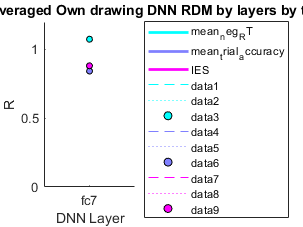


% correlate similarities between subs with intersubject RDMs for each task
cfg.plot_rdm = 0;
plot_dnn_cor_by_layer(d, cfg);

--- correlate generated images of control images with DNN layer --- 

% preparation
cfg.analysis_name = 'Control_drawing_DNN_RDM';
d.DNN.(cfg.dnn).(cfg.analysis_name) = struct;
cfg.plot_rdm = 1;
drw_group = 'control';
cfg.colormap = cfg.colormaps.ctrDrwColormap;
cfg.folder_path = fullfile(cfg.parent_dir, 'image_similarities','drawings_draw3D', 'draw3D_images_exp2', drw_group);

% load images
images.(cfg.analysis_name) = load_images(cfg);

Loaded image: 201_bed_copy_gen1.png
Loaded image: 201_bed_copy_gen2.png
Loaded image: 201_bed_copy_gen3.png
Loaded image: 202_bed_copy_gen1.png
Loaded image: 202_bed_copy_gen2.png
Loaded image: 202_bed_copy_gen3.png
Loaded image: 203_bed_copy_gen1.png
Loaded image: 203_bed_copy_gen2.png
Loaded image: 203_bed_copy_gen3.png
Loaded image: 204_bed_copy_gen1.png
Loaded image: 204_bed_copy_gen2.png
Loaded image: 204_bed_copy_gen3.png
Loaded image: 205_bed_copy_gen1.png
Loaded image: 205_bed_copy_gen2.png
Loaded image: 205_bed_copy_gen3.png
Loaded image: 206_bed_copy_gen1.png
Loaded image: 206_bed_copy_gen2.png
Loaded image: 206_bed_copy_gen3.png
Loaded image: 207_bed_copy_gen1.png
Loaded image: 207_bed_copy_gen2.png
Loaded image: 207_bed_copy_gen3.png
Loaded image: 208_bed_copy_gen1.png
Loaded image: 208_bed_copy_gen2.png
Loaded image: 208_bed_copy_gen3.png
Loaded image: 209_bed_copy_gen1.png
Loaded image: 209_bed_copy_gen2.png
Loaded image: 209_bed_copy_gen3.png
Loaded image: 210_bed_copy_g

analysis Control_drawing_DNN_RDM - layer #1 - category: bedroom
Length of labels do not match matrix dimensions


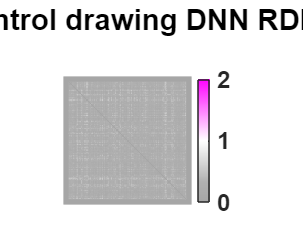

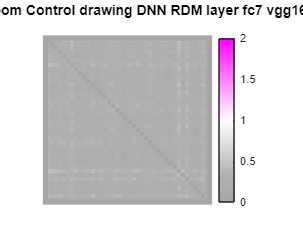

analysis Control_drawing_DNN_RDM - layer #1 - category: livingroom
Length of labels do not match matrix dimensions


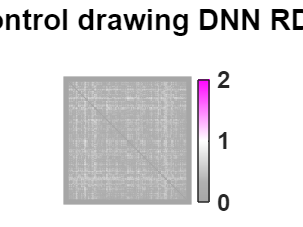

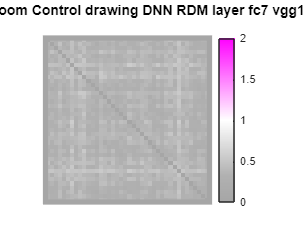


% get correaltion of images from DNN
[d, cfg] = get_dnn_layer_similarity(d, images.(cfg.analysis_name), cfg);

Calculated correaltion of DNN layer representation of Control_drawing_DNN_RDM with task RDMs for bedroom
Calculated correaltion of DNN layer representation of Control_drawing_DNN_RDM with task RDMs for livingroom


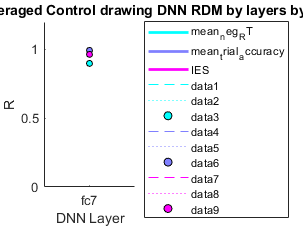


% correlate similarities between subs with intersubject RDMs for each task
cfg.plot_rdm = 0;
plot_dnn_cor_by_layer(d, cfg);

--- correlate original images of typical drawings with DNN layer --- 

% % preparation
% cfg.analysis_name = 'Original_own_drawing_DNN_RDM';
% d.DNN.(cfg.dnn).(cfg.analysis_name) = struct;
% drw_group = 'own';
% cfg.file_format = 'jpg';
% cfg.folder_path = fullfile(cfg.parent_dir, 'image_similarities','drawings_draw3D', 'used_drawings_exp2', drw_group);
% 
% % load images
% images.(cfg.analysis_name) = load_images(cfg);
% 
% % get correaltion of images from DNN
% [d, cfg] = get_dnn_layer_similarity(d, images.(cfg.analysis_name), cfg);
% 
% % correlate similarities between subs with intersubject RDMs for each task
% plot_dnn_cor_by_layer(d, cfg);

--- correlate original images of control images with DNN layer --- 

% % preparation
% cfg.analysis_name = 'Original_control_drawing_DNN_RDM';
% d.DNN.(cfg.dnn).(cfg.analysis_name) = struct;
% drw_group = 'control';
% cfg.folder_path = fullfile(cfg.parent_dir, 'image_similarities','drawings_draw3D', 'used_drawings_exp2', drw_group);
% 
% % load images
% images.(cfg.analysis_name) = load_images(cfg);
% 
% % get correaltion of images from DNN
% [d, cfg] = get_dnn_layer_similarity(d, images.(cfg.analysis_name), cfg);
% 
% % correlate similarities between subs with intersubject RDMs for each task
% plot_dnn_cor_by_layer(d, cfg);

--- task correaltions ---

% % calculate and plot the correlations between task RDMs and predictor RDMs
% 
% % define conditions
% % cfg.dnns  = {'googlenet_places365','vggnet16_places365','vgg16_imagenet'};
% % cfg.dnns = {dnn};
% cfg.dnns  = {'vgg16_imagenet'};
% cfg.RDMs_of_interest = {'Neg_RT', 'accuracy', 'IES'};
% cfg.predictor_RDMs = {'generated_images_ctr_dnn_layer_early','generated_images_ctr_dnn_layer_medium', 'generated_images_ctr_dnn_layer_late',...
%     'generated_images_own_dnn_layer_early','generated_images_own_dnn_layer_medium', 'generated_images_own_dnn_layer_late'...
%     'original_images_ctr_dnn_layer_early','original_images_ctr_dnn_layer_medium', 'original_images_ctr_dnn_layer_late',...
%     'original_images_own_dnn_layer_early','original_images_own_dnn_layer_medium', 'original_images_own_dnn_layer_late'};
% cfg.mds = 0;
% cfg.rdm_name_prefix = 'RDM_of_RDMs_';
% cfg.partial_cor = 0;
% cfg.plotting = 1;
% 
% % run correaltions
% [cor_plots, d] = RDM_of_RDMs(cor_plots, d, cfg);


--- task correaltions with partial correaltion ---

% % calculate and plot the partial correlations between task RDMs and predictor RDMs
% 
% % define conditions
% cfg.dnns  = {'vgg16_imagenet'};
% cfg.RDMs_of_interest = {'Neg_RT', 'accuracy', 'IES'};
% cfg.predictor_RDMs = {'generated_images_ctr_dnn_layer_late', 'generated_images_own_dnn_layer_late'};
% cfg.mds = 0;
% 
% % define which preditor should be partialed out
% cfg.partial_cor = 1;
% cfg.rdm_name_prefix = 'partial_RDM_of_RDMs_';
% cfg.RDM_to_partial_out =  {'Typical Images vgg16_imagenet Late', 'Control Images vgg16_imagenet Late'};
% 
% 
% % run partial correaltions
% [cor_plots, d] = RDM_of_RDMs(cor_plots, d, cfg);


--- compare stimulus image with drawings and photo --- 

% % correlate task performance to similarity of stimulus images
% d = img_predicting_tasks(d, cfg, images);
% 
% % get difference between wihtin and between category similarities wiht
% % cadidate images
% d.img_id_table.within_vs_between_typ_drw = d.img_id_table.cor_to_typ_drw -...
%     d.img_id_table.other_cate_cor_to_typ_drw;
% d.img_id_table.within_vs_between_ctr_drw = d.img_id_table.cor_to_ctr_drw -...
%     d.img_id_table.other_cate_cor_to_ctr_drw;
% 
% % get correllation to task performances
% cfg.variables_of_interest = {'mean_neg_RT','mean_trial_accuracy',...
%     'cor_to_ctr_drw', 'cor_to_typ_drw'...
%     'within_vs_between_typ_drw', 'within_vs_between_ctr_drw'};
% [~, d] = plot_rating_cor(d, cfg);


--- replicate Wang et al ---

% cfg.variables_of_interest = {'mean_neg_RT','mean_trial_accuracy'};
% 
% d = graded_similarity_analysis(d, cfg);


--- Compare the intersubject task RDMs to the predictor RDMs

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of IES bedroom is done
20% of permutations of IES bedroom is done
30% of permutations of IES bedroom is done
40% of permutations of IES bedroom is done
50% of permutations of IES bedroom is done
60% of permutations of IES bedroom is done
70% of permutations of IES bedroom is done
80% of permutations of IES bedroom is done
90% of permutations of IES bedroom is done
100% of permutations of IES bedroom is done
Compare inter-subject RDM of IES with correaltion of predictor RDMs - bedroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of IES livingroom is done
20% of permutations of IES livingroom is done
30% of permutations of IES livingroom is done
40% of permutations of IES livingroom is done
50% of permutations of IES livingroom is done
60% of permutations of IES livingroom is done
70% of permutations of IES livingroom is done
80% of permutations of IES livingroom is done
90% of 

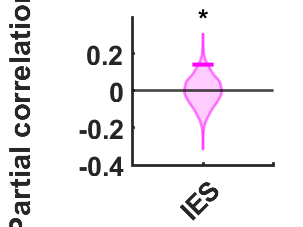

% preparation
cfg.partial_cor = true;
cfg.plot_rdm = true;
cfg.plotting = true;
cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
cfg.predictor_RDMs = {'generated_images_own_dnn_layer_late', 'generated_images_ctr_dnn_layer_late'};
cfg.tasks_of_interest = {'IES'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'violin';
cfg.show_single_cate = false;
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.permutation_type = 'row_col_shuffle_ref';
cfg.add_legend = false;
cfg.ylim = [-0.4, 0.4];
cfg.plotting_predictors = 1;
cfg.plott_gap = 0;
cfg.partial_correlation_type = 'pearson';

d = compare_task_RDMs_to_predictor_RDMs(d, cfg);

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of IES bedroom is done
20% of permutations of IES bedroom is done
30% of permutations of IES bedroom is done
40% of permutations of IES bedroom is done
50% of permutations of IES bedroom is done
60% of permutations of IES bedroom is done
70% of permutations of IES bedroom is done
80% of permutations of IES bedroom is done
90% of permutations of IES bedroom is done
100% of permutations of IES bedroom is done
Compare inter-subject RDM of IES with correaltion of predictor RDMs - bedroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of IES livingroom is done
20% of permutations of IES livingroom is done
30% of permutations of IES livingroom is done
40% of permutations of IES livingroom is done
50% of permutations of IES livingroom is done
60% of permutations of IES livingroom is done
70% of permutations of IES livingroom is done
80% of permutations of IES livingroom is done
90% of 

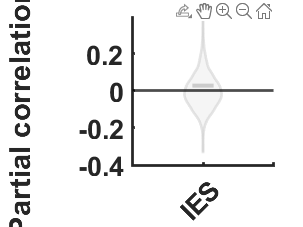


cfg.plotting_predictors = 2;
d = compare_task_RDMs_to_predictor_RDMs(d, cfg);

--- use clip model with original drawings to predict task similarities

% % preparation
% cfg.layer_type = 'late';
% cfg.plot_rdm = false;
% cfg.analysis_names = {'Original_own_drawing_DNN_RDM','Original_control_drawing_DNN_RDM'};
% cfg.dnns = {'clip'};
% 
% % get clip similarities
% [d, images] = dnn_network_similarity(d, images, cfg);
% 
% 
% % preparation
% cfg.partial_cor = true;
% cfg.RDM_to_partial_out = {'Original clip typical image','Original clip control image'};
% cfg.predictor_RDMs = {'original_own_clip_model', 'original_control_clip_model'};
% cfg.tasks_of_interest = {'IES'};
% cfg.dnns = {'clip'};
% cfg.show_single_cate = false;
% cfg.permutation_test = true;
% cfg.order_predictors = false;
% cfg.n_permutations = 5000;
% cfg.permutation_type = 'row_col_shuffle_ref';
% 
% % run comparison
% cfg.save_name = 'compare_task_RDMs_to_predictor_RDMs_clip';
% d = compare_task_RDMs_to_predictor_RDMs(d, cfg);


--- make mds of similarity spaces

% get feature acivation for missing layer

% % preparation
% cfg.dnn = 'vgg16_imagenet';
% cfg.layer_type = 'early_mid_late';
% [cfg.parent_dir, ~, ~] = fileparts(pwd);
% cfg.file_format = 'png';
% cfg.plot_rdm = false;
% cfg.RDM_of_DNNS = true;
% 
% % own
% cfg.analysis_name = 'Own_drawing_DNN_RDM';
% drw_group = 'own';
% cfg.folder_path = fullfile(cfg.parent_dir, 'image_similarities','drawings_draw3D', 'draw3D_images_exp2', drw_group);
% images.(cfg.analysis_name) = load_images(cfg);
% [d, cfg] = get_dnn_layer_similarity(d, images.(cfg.analysis_name), cfg);
% 
% % control
% cfg.analysis_name = 'Control_drawing_DNN_RDM';
% drw_group = 'control';
% cfg.folder_path = fullfile(cfg.parent_dir, 'image_similarities','drawings_draw3D', 'draw3D_images_exp2', drw_group);
% images.(cfg.analysis_name) = load_images(cfg);
% [d, cfg] = get_dnn_layer_similarity(d, images.(cfg.analysis_name), cfg);
% 
% % make mds
% 
% % preparation
% cfg.layer_type = 'late';
% cfg.plot_rdm = false;
% cfg.mds = true;
% cfg.partial_cor = false;
% cfg.dnns  = {'vgg16_imagenet'};
% cfg.RDMs_of_interest = {'Neg_RT', 'accuracy', 'IES'};
% cfg.predictor_RDMs = {'generated_images_ctr_dnn_layer_early', 'generated_images_own_dnn_layer_early',...
%     'generated_images_ctr_dnn_layer_medium', 'generated_images_own_dnn_layer_medium'...
%     'generated_images_ctr_dnn_layer_late', 'generated_images_own_dnn_layer_late'};
% 
% 
% % run partial correaltions
% [~, d] = RDM_of_RDMs([], d, cfg);


% 
save('d2.mat', 'd', '-v7.3')
save('cfg2.mat', 'cfg', '-v7.3')
